# Matlab eta integralen kalkulua

Tutorial honetan ikusiko dugu nola egin integralak Matlaben bidez.

clear all

### Integral sinbolikoak $\mathbb R$-n.

Hasteko, matlabek integral sinbolikoak kalkula ditzake.

syms  a x y t

Integrazio sinbolikoak egiteko int(funtzioa,aldagaia,behe-muga, gohi muga) jarri behar ditu. Adibidez,

int(a*x^2,x,0,1)

$$ans = \frac{a}{3}$$

Aldagairik zehazten ez badiogu, defektuz x aldagaia integratuko du.

int(a*x^2*y^3,0,1)

$$ans = \frac{a\,y^{3}}{3}$$

Gainera, integral sinbolikoa erabil daiteke primitibak lortzeko, funtio sinboliko bezala. Behe borne bezala 0 hartzen du, eta goi bornea intgratzen ari zaren aldagai sinbolikoa. Adibidez,

g(x)=int(a*x^2)

$$g(x) = \frac{a\,x^{3}}{3}$$

Integral sinbolikoa egitean honako hau kontuan izan behar dugu: funtzio batzuen primitiba ezin da adierazi oinarrizko funtzioen batura, biderkadura edo konposaketa bezala. Esate baterako, $e^{x^2}$ edo $\frac{1}{\ln(t)}$:

int(exp(x^2),0,1)

$$ans = \frac{\sqrt{\pi }\,\mathrm{erfi}\left(1\right)}{2}$$

int(1/log(t),2,3)

$$ans = \mathrm{logint}\left(3\right)-\mathrm{logint}\left(2\right)$$

Kasu honetan **logint** eta **erfi** bezala adierazten du; hain zuzen ere funtzio hauen integrala. Noski, funtzio hauek famatuak dira probabilitatean (Gausiana) edo zenbaki teorian (lehenen distribuzioan) agertzen direlako, baina zeozer "artifizialago" saiatzen ari garenean, ba ez du ezer egiten. 

int(sin(t)/(log(t))^2,2,3)

$$ans = \int_{2}^{3}\frac{\sin\left(t\right)}{{\log\left(t\right)}^{2}}\mathrm{d}t$$

Zorionez, emaitza jakiteko nahikoa da Matlabi esatea zenbaki bat bezala adierazteko, eta horretarako nahikoa da **double** komandoa erabiltzea:

double(int(exp(x^2),0,1))

ans = 1.4627

double(int(sin(t)/(log(t))^2,2,3))

ans = 0.8045

Emango dizue emaitzaren hurbilpen bat. Gogoratu, Matlabek bere baitan dezimal gehiago kalkulatuko ditu. Dezimal horiek ikusteko, nahikoa da **format long** idaztea.

### Integral bikoitzak eta hirukoitzak

Matlaben kalkulu sinbolikoa erabili daiteke integral bikoitzak eta hirukoitzak kalkulatzeko orduan. Horretarako, nahikoa da bi edo hiru integral aldi berean kalkulatzea.

syms x y z

Adibidez, $xy$-ren integrala kalkulatu nahi badugu $[0,1]^2$-n.

int(int(x*y,x,0,1),y,0,1)

$$ans = \frac{1}{4}$$

Edo $\sin(\pi(x+y+z))$ kalkulatu nahi badugu $[0,1]^3$, gogoratuz Matlaben $\pi$ zenbakia jada konfiguratuta dagoela eta nahikoa dela **pi **idaztea:

int(int(int(sin(pi*(x+y+z)/3),x,0,1),y,0,1),z,0,1)

$$ans = \frac{27}{\pi^{3}}$$

Emaitzaren hurbilpen bat izateko erabil dezakegu **double **komandoa: 

double(int(int(int(sin(pi*(x+y+z)/3),x,0,1),y,0,1),z,0,1))

ans = 0.8708

Integral sinbolikoa duen abantaila da mugak. Adibidez, $y=x^3$ eta $y=x$ mugatutako eremuan integratu nahi badugu $xy$ funtzioa:

int(int(x*y,y,x^3,x),x,0,1)

$$ans = \frac{1}{16}$$

Era berean $x=y$ eta $x=y^2$ artean integratu nahi badugu $xy$ funtzioa:

int(int(x*y,x,y^2,y),y,0,1)

$$ans = \frac{1}{24}$$

Horrela ere kalkula daitezke integralak 3 dimentsiotan. Hori, zuentzat uzten dut: 

clear x y

### Matlaben integral bikoitzak eremuaren parametrizazioa ez dakizunean.

Integral sinbolikoa bakarrik balio du eremuaren paremtrizazioa ondo dakigunean. Bestela, **integral2** eta **integral3** erabili behar dira.  Zenbakizko metodoak (hurbilpenak) erabiliz kalkulatzen dizkizu  (ez da zehatza), eta @funtzioak erabili behar  dira. Erabiliko dugu $f(x,y)=xy\sin(\pi x/2)sin(\pi y/2)$ funtzioaren integrala$x^2+y^2\leq 1$ eremuan kalkulatzeko. 

Hasteko, definituko dugu @funtzioa bat zein integrazio domeinuan nahi dugun balioa hartzen duen, eta handik kanpo zero. Erabili behar dugu .* eta .^ bektorretan ebaluatzeko kalkuluak gaiz gai egiteko. 

f=@(x,y) x.*y.*sin(pi*x/2).*sin(pi*y/2).*double(x.^2+y.^2<=1);

Gogoratu, bektoreen arteko biderketa idatzi behar da. Gogoratu ==, <=, >=, <, > eta =~ dira eragile logikoak bat edo zeroitzultzen dutena (=~ ezberdin esan nahi du). 

integral2(f,-1,1,-1,1) %Honekin esaten diogu f integretzeko, lehenengo aldagaia -1eta 1era, eta bigarren aldagaia -1eta 1era. 

ans = 0.2349

Hiru dimentsiotan antzera kalkula daitezke integralak. Noski, zirkuluaren kasuan oso erraz parametriza daiteke nondik nora doazen integral bakoitza, baina domeinua erraz parametriza ezin daitekeenean horrelako formulak erabili behar dira (adibidez $xy>1$, $x^2+y^2<1$ eta $x+y\geq\frac{1}{2}$ aldi berean betetzen duen eremua).

### Integrazio eremuen mugen irudikapenak $\mathbb R^2$-n.

Ikus dezagun nola irudikatu Matlaben integrazio ermuen mugak.  Demagun y=x eta y=x^2 inguratuko eremua irudikatu nahi duzuela. 

%Horretarako nahikoa da **fplot** eta **hold on** aginduak erabiltzea.

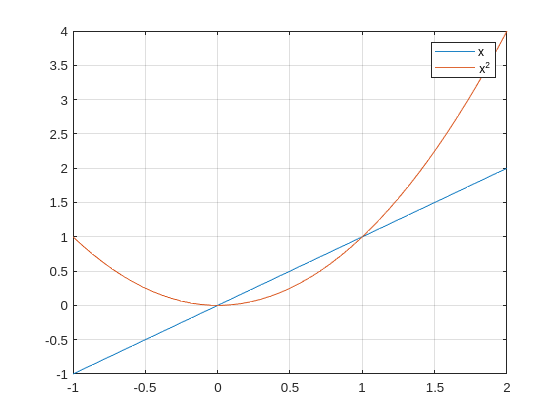

syms x
fplot(x,[-1,2])
hold on 
fplot(x^2,[-1,2])
hold off
legend("x","x^2") %Kurbak zer diren esatkeo. 
grid on 

Eremua bi kurben artean dagoen eremu bornatua da.

clear x

### Eremuen marrazkiak $x=f(y)$ motako funtzioekin.

Kurbak $x=f(y)$ motakoak baldin badira fplot erabili behar da, baina funtzio baten ordez bi funtzioko bektorea emanda. Izan ere, **fplot(f_1(y),y,[y_min, y_max])** irudikatzen du $x=f(y)$ kurba. Orokorrena **fplot(f_1(t),f_2(t),[t_min t_max])** balio du $(f_1(t),f_2(t))$irudikatzeko, baina hemen kasu berezi batekin ari gara lan egiten, eta  **fplot(f(x),[xmin xmax])** moduko zeozer idazten dugunean, aurreko atalean bezala, $y=f(x)$ kurba irudikatzen du. Bai, **fplot** gauza bat baino gehiago egin ditzake sarrera gai kopuruen arabera, hori barneratu behar da. Ikus dezagun nola erabili aurrekoa, $x=y$ eta $x=y^2$ kurbak marrazteko kurba hauek marraztutako eremua irudikatzeko:

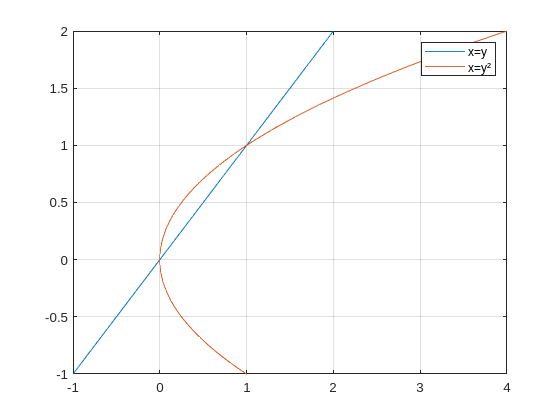

syms y 
fplot(y,y,[-1,2])
hold on
fplot(y^2,y,[-1, 2])%Gogoratu, funtzioa x=y^2 da
hold off
legend("x=y","x=y²") 
grid on

clear y